# **Experimental Demonstration of Power Budgets**

The code below processes the experimental data obtained for demonstrating the power budgets achieved for the simplified receiver

#### Initial Vairable Load

clearvars

% Loading initial data
addpath ExperimentalDataBence;
load('exp_data_1e-2.mat'); % trainSymbs
load('RCOS.mat'); % RRC filter
clear ux;

% Global variable initialisation
Rs=50e9;
linkLength = 40e3;
D = 17;
CLambda = 1550e-9;
c = 299792458; % Speed of light in m/s
SpS=2;

N_CD = ceil(6.67*(D*1e-6)*(CLambda^2)*linkLength*(Rs^2)*SpS/(2*pi*c)) % CD Equalizer Length

N_CD = 29

N_FFT = 2^10

N_FFT = 1024

#### Launch Power = 7dBm

% Launch power = 7dBm

directory7 =  'exp_Keshin_1\7dBm';
addpath 'exp_Keshin_1\7dBm';

NTaps = 55;
Mu_T = 1e-2; Mu_DD = Mu_T;
Mu_p = 1e-2;
runs = 1;
N1 = runs*length(s_qam)/2;
NRemoveF = 12000;
NRemoveB = 5000;

% Received power of -23dBm
data7_23 = dir(fullfile(directory7, '*-23*.mat')); 
BER7_23 = zeros(size(data7_23)); 
for i=1:length(data7_23)
    filename = data7_23(i).name;
    load(filename);
    [~, ~, ~, ~, ~, ~, errArr_23, BER7_23(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
    clear ch1 ch2 ch3 ch4 
end

mean(log10(BER7_23))

ans = -1.7720

var(log10(BER7_23))

ans = 0.0066

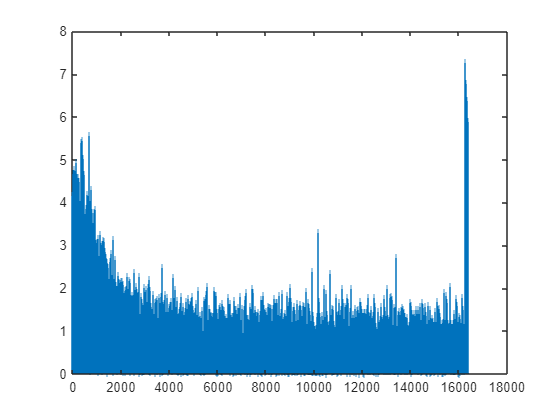


stem([1:length(errArr_23)], abs(errArr_23(:,1)), '|')

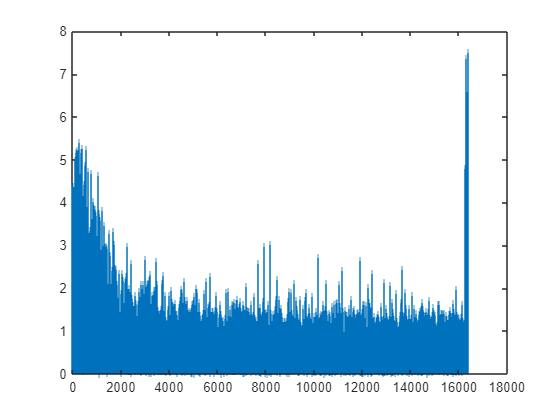

stem([1:length(errArr_23)], abs(errArr_23(:,2)), '|')

% Received power of -22dBm
data7_22 = dir(fullfile(directory7, '*-22*.mat')); 
BER7_22 = zeros(size(data7_22)); 
for i=[1:length(data7_22)-2 length(data7_22)]
    filename = data7_22(i).name;
    load(filename);
    [~, ~, ~, ~, ~, ~, errArr_22, BER7_22(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
    clear ch1 ch2 ch3 ch4 
end

mean(log10(BER7_22))

ans = -Inf

var(log10(BER7_22))

ans = NaN

% Received power of -21dBm
data7_21 = dir(fullfile(directory7, '*-21*.mat')); 
BER7_21 = zeros(size(data7_21)); 
for i=1:length(data7_21)
    filename = data7_21(i).name;
    load(filename);
    [~, ~, ~, ~, ~, ~, errArr_21, BER7_21(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
    clear ch1 ch2 ch3 ch4 
end

mean(log10(BER7_21))

ans = -1.9858

var(log10(BER7_21))

ans = 0.0232

% Received power of -20dBm
data7_20 = dir(fullfile(directory7, '*-20*.mat')); 
BER7_20 = zeros(size(data7_20)); 
for i=1:length(data7_20)-1
    filename = data7_20(i).name;
    load(filename);
    [~, ~, ~, ~, ~, ~, errArr_20, BER7_20(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
    clear ch1 ch2 ch3 ch4 
end

mean(log10(BER7_20(1:end-1)))

ans = -2.0867

var(log10(BER7_20(1:end-1)))

ans = 0.0219

% Received power of -19dBm
data7_19 = dir(fullfile(directory7, '*-19*.mat')); 
BER7_19 = zeros(size(data7_19)); 
for i=1:length(data7_19)
    filename = data7_19(i).name;
    load(filename);
    [~, ~, ~, ~, ~, ~, errArr_19, BER7_19(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
    clear ch1 ch2 ch3 ch4 
end

mean(log10(BER7_19))

ans = -2.1334

var(log10(BER7_19))

ans = 0.0248

NTaps = 55;
Mu_T = 1e-2; Mu_DD = Mu_T;
Mu_p = 1e-2;
runs = 1;
N1 = runs*length(s_qam)/2;
NRemoveF = 12000;
NRemoveB = 5000;

% Received power of -18dBm
data7_18 = dir(fullfile(directory7, '*-18*.mat')); 
BER7_18 = zeros(size(data7_18)); 
for i=[1:4 6:length(data7_18)]
    filename = data7_18(i).name;
    load(filename);
    [~, ~, ~, ~, ~, ~, errArr_18, BER7_18(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
    clear ch1 ch2 ch3 ch4 
end

mean(log10(BER7_18))

ans = -Inf

var(log10(BER7_18))

ans = NaN

% Received power of -17dBm
data7_17 = dir(fullfile(directory7, '*-17*.mat')); 
BER7_17 = zeros(size(data7_17)); 
for i=1:length(data7_17)
    filename = data7_17(i).name;
    load(filename);
    [~, ~, ~, ~, ~, ~, errArr_17, BER7_17(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
    clear ch1 ch2 ch3 ch4 
end

mean(log10(BER7_17))

ans = -2.4739

var(log10(BER7_17))

ans = 0.0306

% Received power of -16dBm
data7_16 = dir(fullfile(directory7, '*-16*.mat')); 
BER7_16 = zeros(size(data7_16)); 
for i=1:length(data7_16)
    filename = data7_16(i).name;
    load(filename);
    [~, ~, ~, ~, ~, ~, errArr_16, BER7_16(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
    clear ch1 ch2 ch3 ch4 
end

mean(log10(BER7_16))

ans = -2.6171

var(log10(BER7_16))

ans = 0.0319

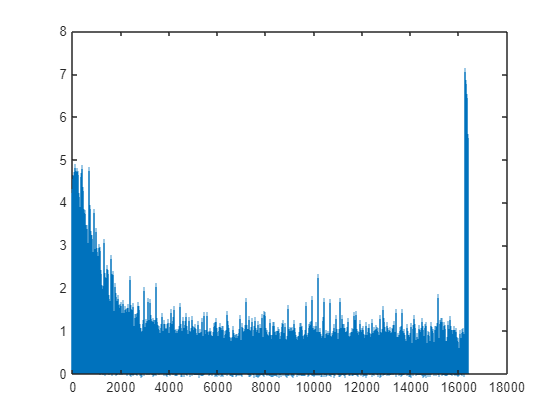

stem([1:length(errArr_16)], abs(errArr_16(:,1)), '|')

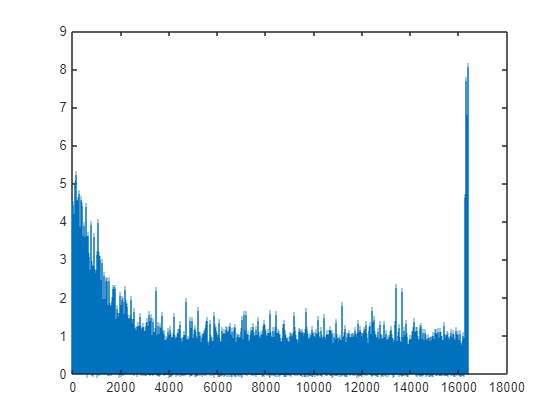

stem([1:length(errArr_16)], abs(errArr_16(:,2)), '|')

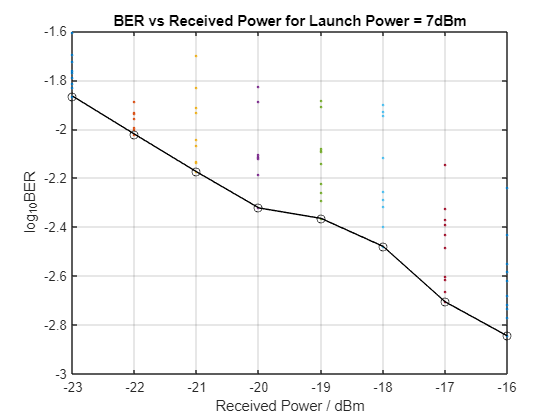

% Calculating best fit line
BER7_mean = min(ClosestToMean([BER7_23 BER7_22 BER7_21 BER7_20 BER7_19 BER7_18 BER7_17 BER7_16], 3));

% Plotting BERs
plot(repelem(-23, 10, 1), log10(BER7_23), '.', Linewidth=4)
hold on
plot(repelem(-22, 10, 1), log10(BER7_22), '.', Linewidth=4)
plot(repelem(-21, 10, 1), log10(BER7_21), '.', Linewidth=4)
plot(repelem(-20, 10, 1), log10(BER7_20), '.', Linewidth=4)
plot(repelem(-19, 10, 1), log10(BER7_19), '.', Linewidth=4)
plot(repelem(-18, 10, 1), log10(BER7_18), '.', Linewidth=4)
plot(repelem(-17, 10, 1), log10(BER7_17), '.', Linewidth=4)
plot(repelem(-16, 10, 1), log10(BER7_16), '.', Linewidth=4)
plot([-23:-16], log10(BER7_mean), 'ko-')
title('BER vs Received Power for Launch Power = 7dBm')
xlabel('Received Power / dBm')
ylabel('log_{10}BER')
hold off
grid on

#### Launch Power = 8dBm

% % Launch power = 8dBm
% 
% directory8 =  'exp_Keshin_1\8dBm';
% addpath 'exp_Keshin_1\8dBm';
% 
% NTaps = 125;
% Mu_T = 2e-4; Mu_DD = Mu_T;
% Mu_p = 1e-2;
% runs = 5;
% N1 = runs*length(s_qam)/2;
% NRemoveF = 10000;
% NRemoveB = 10000;

% % Received power of -23dBm
% data8_23 = dir(fullfile(directory8, '*-23*.mat')); 
% BER8_23 = zeros(size(data8_23)); 
% for i=1:length(data8_23)
%     filename = data8_23(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_23, BER8_23(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER8_23))
% var(log10(BER8_23))

% % PLotting error variation
% stem([1:length(errArr_23)], abs(errArr_23(:,1)), '|')
% stem([1:length(errArr_23)], abs(errArr_23(:,2)), '|')

% % Received power of -22dBm
% data8_22 = dir(fullfile(directory8, '*-22*.mat')); 
% BER8_22 = zeros(size(data8_22)); 
% for i=[1:length(data8_22)-2 length(data8_22)]
%     filename = data8_22(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_22, BER8_22(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER8_22))
% var(log10(BER8_22))

% % Received power of -21dBm
% data8_21 = dir(fullfile(directory8, '*-21*.mat')); 
% BER8_21 = zeros(size(data8_21)); 
% for i=1:length(data8_21)
%     filename = data8_21(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_21, BER8_21(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER8_21))
% var(log10(BER8_21))

% % Received power of -20dBm
% data8_20 = dir(fullfile(directory8, '*-20*.mat')); 
% BER8_20 = zeros(size(data8_20)); 
% for i=1:length(data8_20)-1
%     filename = data8_20(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_20, BER8_20(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER8_20(1:end-1)))
% var(log10(BER8_20(1:end-1)))

% % Received power of -19dBm
% data8_19 = dir(fullfile(directory8, '*-19*.mat')); 
% BER8_19 = zeros(size(data8_19)); 
% for i=1:length(data8_19)
%     filename = data8_19(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_19, BER8_19(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER8_19))
% var(log10(BER8_19))

% NTaps = 125;
% Mu_T = 2e-4; Mu_DD = Mu_T;
% Mu_p = 1e-2;
% N1 = runs*length(s_qam)/2;
% NRemoveF = 10000;
% NRemoveB = 10000;
% 
% % Received power of -18dBm
% data8_18 = dir(fullfile(directory8, '*-18*.mat')); 
% BER8_18 = zeros(size(data8_18)); 
% for i=[1:length(data8_18)]
%     filename = data8_18(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_18, BER8_18(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER8_18))
% var(log10(BER8_18))

% % Received power of -17dBm
% data8_17 = dir(fullfile(directory8, '*-17*.mat')); 
% BER8_17 = zeros(size(data8_17)); 
% for i=1:length(data8_17)
%     filename = data8_17(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_17, BER8_17(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER8_17))
% var(log10(BER8_17))

% % Received power of -16dBm
% data8_16 = dir(fullfile(directory8, '*-16*.mat')); 
% BER8_16 = zeros(size(data8_16)); 
% for i=1:length(data8_16)
%     filename = data8_16(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_16, BER8_16(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER8_16))
% var(log10(BER8_16))

% % PLotting error variation
% stem([1:length(errArr_16)], abs(errArr_16(:,1)), '|')
% stem([1:length(errArr_16)], abs(errArr_16(:,2)), '|')

% % Calculating best fit line
% BER8_mean = min(ClosestToMean([BER8_23 BER8_22 BER8_21 BER8_20 BER8_19 BER8_18 BER8_17 BER8_16], 3));
% 
% % Plotting BERs
% plot(repelem(-23, 10, 1), log10(BER8_23), '.', Linewidth=4)
% hold on
% plot(repelem(-22, 10, 1), log10(BER8_22), '.', Linewidth=4)
% plot(repelem(-21, 10, 1), log10(BER8_21), '.', Linewidth=4)
% plot(repelem(-20, 10, 1), log10(BER8_20), '.', Linewidth=4)
% plot(repelem(-19, 10, 1), log10(BER8_19), '.', Linewidth=4)
% plot(repelem(-18, 10, 1), log10(BER8_18), '.', Linewidth=4)
% plot(repelem(-17, 10, 1), log10(BER8_17), '.', Linewidth=4)
% plot(repelem(-16, 10, 1), log10(BER8_16), '.', Linewidth=4)
% plot([-23:-16], log10(BER8_mean), 'ko-')
% title('BER vs Received Power for Launch Power = 8dBm')
% xlabel('Received Power / dBm')
% ylabel('log_{10}BER')
% hold off
% grid on

#### Launch Power = 9dBm

% Launch power = 9dBm

directory9 =  'exp_Keshin_1\9dBm';
addpath 'exp_Keshin_1\9dBm';

NTaps = 125;
Mu_T = 2e-4; Mu_DD = Mu_T;
Mu_p = 1e-2;
runs = 5;
N1 = runs*length(s_qam)/2;
NRemoveF = 10000;
NRemoveB = 10000;

% Received power of -23dBm
data9_23 = dir(fullfile(directory9, '*-23*.mat')); 
BER9_23 = zeros(size(data9_23)); 
for i=[1:4 6:length(data9_23)]
    filename = data9_23(i).name;
    load(filename);
    [~, ~, ~, ~, ~, ~, errArr_23, BER9_23(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
    clear ch1 ch2 ch3 ch4 
end

mean(log10(BER9_23))

ans = -Inf

var(log10(BER9_23))

ans = NaN

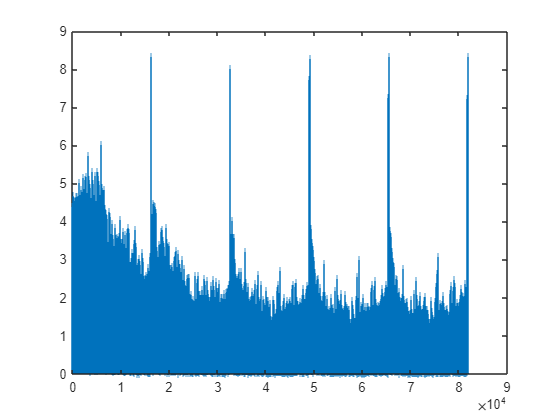

% PLotting error variation
stem([1:length(errArr_23)], abs(errArr_23(:,1)), '|')

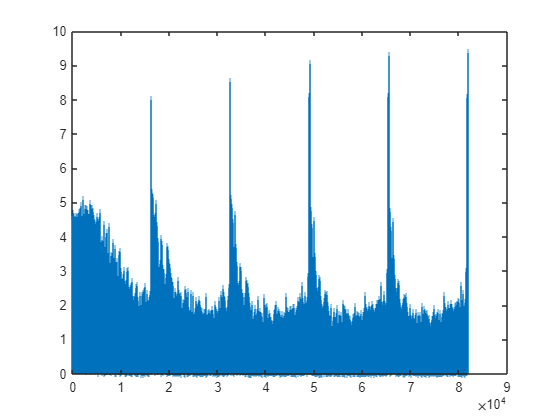

stem([1:length(errArr_23)], abs(errArr_23(:,2)), '|')

% Received power of -22dBm
data9_22 = dir(fullfile(directory9, '*-22*.mat')); 
BER9_22 = zeros(size(data9_22)); 
for i=[1:6 9:length(data9_22)]
    filename = data9_22(i).name;
    load(filename);
    [~, ~, ~, ~, ~, ~, errArr_22, BER9_22(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
    clear ch1 ch2 ch3 ch4 
end

mean(log10(BER9_22))

ans = -Inf

var(log10(BER9_22))

ans = NaN

% Received power of -21dBm
data9_21 = dir(fullfile(directory9, '*-21*.mat')); 
BER9_21 = zeros(size(data9_21)); 
for i=1:length(data9_21)
    filename = data9_21(i).name;
    load(filename);
    [~, ~, ~, ~, ~, ~, errArr_21, BER9_21(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
    clear ch1 ch2 ch3 ch4 
end

mean(log10(BER9_21))

ans = -1.8938

var(log10(BER9_21))

ans = 0.0110

% Received power of -20dBm
data9_20 = dir(fullfile(directory9, '*-20*.mat')); 
BER9_20 = zeros(size(data9_20)); 
for i=[1 3:length(data9_20)-1]
    filename = data9_20(i).name;
    load(filename);
    [~, ~, ~, ~, ~, ~, errArr_20, BER9_20(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
    clear ch1 ch2 ch3 ch4 
end

mean(log10(BER9_20(1:end-1)))

ans = -Inf

var(log10(BER9_20(1:end-1)))

ans = NaN

% Received power of -19dBm
data9_19 = dir(fullfile(directory9, '*-19*.mat')); 
BER9_19 = zeros(size(data9_19)); 
for i=1:length(data9_19)
    filename = data9_19(i).name;
    load(filename);
    [~, ~, ~, ~, ~, ~, errArr_19, BER9_19(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
    clear ch1 ch2 ch3 ch4 
end

mean(log10(BER9_19))

ans = -1.7517

var(log10(BER9_19))

ans = 0.0934

NTaps = 125;
Mu_T = 2e-4; Mu_DD = Mu_T;
Mu_p = 1e-2;
N1 = runs*length(s_qam)/2;
NRemoveF = 10000;
NRemoveB = 10000;

% Received power of -18dBm
data9_18 = dir(fullfile(directory9, '*-18*.mat')); 
BER9_18 = zeros(size(data9_18)); 
for i=[1:length(data9_18)]
    filename = data9_18(i).name;
    load(filename);
    [~, ~, ~, ~, ~, ~, errArr_18, BER9_18(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
    clear ch1 ch2 ch3 ch4 
end

mean(log10(BER9_18))

ans = -1.8990

var(log10(BER9_18))

ans = 0.0288

% Received power of -17dBm
data9_17 = dir(fullfile(directory9, '*-17*.mat')); 
BER9_17 = zeros(size(data9_17)); 
for i=[1:2 5:length(data9_17)]
    filename = data9_17(i).name;
    load(filename);
    [~, ~, ~, ~, ~, ~, errArr_17, BER9_17(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
    clear ch1 ch2 ch3 ch4 
end

mean(log10(BER9_17))

ans = -Inf

var(log10(BER9_17))

ans = NaN

% Received power of -16dBm
data9_16 = dir(fullfile(directory9, '*-16*.mat')); 
BER9_16 = zeros(size(data9_16)); 
for i=1:length(data9_16)
    filename = data9_16(i).name;
    load(filename);
    [~, ~, ~, ~, ~, ~, errArr_16, BER9_16(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
    clear ch1 ch2 ch3 ch4 
end

mean(log10(BER9_16))

ans = -2.1823

var(log10(BER9_16))

ans = 0.0406

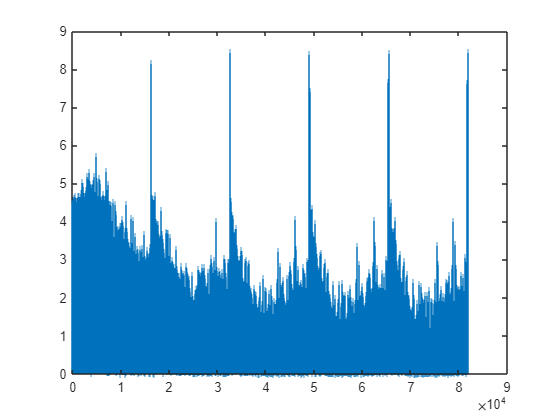

% PLotting error variation
stem([1:length(errArr_16)], abs(errArr_16(:,1)), '|')

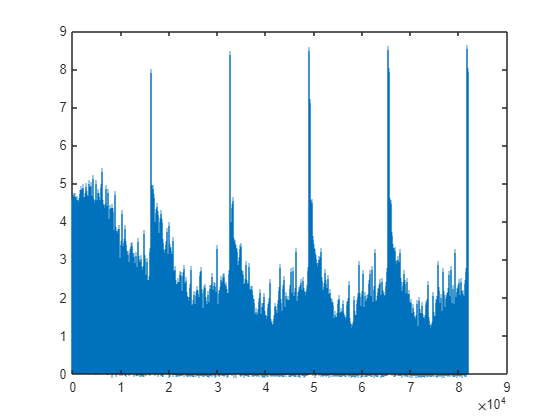

stem([1:length(errArr_16)], abs(errArr_16(:,2)), '|')

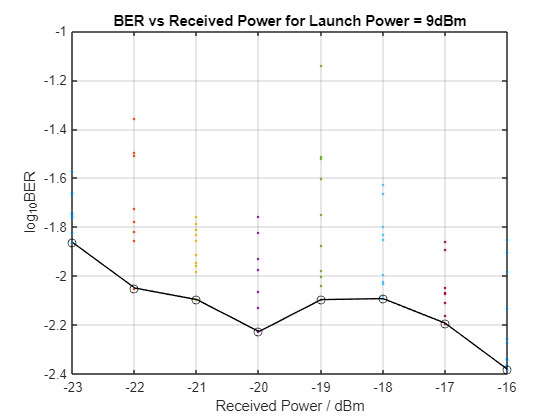

% Calculating best fit line
BER9_mean = min(ClosestToMean([BER9_23 BER9_22 BER9_21 BER9_20 BER9_19 BER9_18 BER9_17 BER9_16], 3));

% Plotting BERs

plot(repelem(-23, 10, 1), log10(BER9_23), '.', Linewidth=4)
hold on
plot(repelem(-22, 10, 1), log10(BER9_22), '.', Linewidth=4)
plot(repelem(-21, 10, 1), log10(BER9_21), '.', Linewidth=4)
plot(repelem(-20, 10, 1), log10(BER9_20), '.', Linewidth=4)
plot(repelem(-19, 10, 1), log10(BER9_19), '.', Linewidth=4)
plot(repelem(-18, 10, 1), log10(BER9_18), '.', Linewidth=4)
plot(repelem(-17, 10, 1), log10(BER9_17), '.', Linewidth=4)
plot(repelem(-16, 10, 1), log10(BER9_16), '.', Linewidth=4)
plot([-23:-16], log10(BER9_mean), 'ko-')
title('BER vs Received Power for Launch Power = 9dBm')
xlabel('Received Power / dBm')
ylabel('log_{10}BER')
hold off
grid on

#### Launch Power = 10dBm

% % Launch power = 10dBm
% 
% directory10 =  'exp_Keshin_1\10dBm';
% addpath 'exp_Keshin_1\10dBm';
% 
% NTaps = 125;
% Mu_T = 5e-4; Mu_DD = Mu_T;
% Mu_p = 1e-2;
% runs = 5;
% N1 = runs*length(s_qam)/2;
% NRemoveF = 12000;
% NRemoveB = 8000;

% % Received power of -23dBm
% data10_23 = dir(fullfile(directory10, '*-23*.mat')); 
% BER10_23 = zeros(size(data10_23)); 
% for i=[1:5 7:length(data10_23)]
%     filename = data10_23(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_23, BER10_23(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER10_23))
% var(log10(BER10_23))

% % PLotting error variation
% stem([1:length(errArr_23)], abs(errArr_23(:,1)), '|')
% stem([1:length(errArr_23)], abs(errArr_23(:,2)), '|')

% % Received power of -22dBm
% data10_22 = dir(fullfile(directory10, '*-22*.mat')); 
% BER10_22 = zeros(size(data10_22)); 
% for i=1:length(data10_22)
%     filename = data10_22(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_22, BER10_22(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER10_22))
% var(log10(BER10_22))

% % Received power of -21dBm
% data10_21 = dir(fullfile(directory10, '*-21*.mat')); 
% BER10_21 = zeros(size(data10_21)); 
% for i=1:length(data10_21)
%     filename = data10_21(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_21, BER10_21(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER10_21))
% var(log10(BER10_21))

% % Received power of -20dBm
% data10_20 = dir(fullfile(directory10, '*-20*.mat')); 
% BER10_20 = zeros(size(data10_20)); 
% for i=1:length(data10_20)
%     filename = data10_20(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_20, BER10_20(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER10_20(1:end-1)))
% var(log10(BER10_20(1:end-1)))

% % Received power of -19dBm
% data10_19 = dir(fullfile(directory10, '*-19*.mat')); 
% BER10_19 = zeros(size(data10_19)); 
% for i=1:length(data10_19)
%     filename = data10_19(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_19, BER10_19(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER10_19))
% var(log10(BER10_19))

% NTaps = 125;
% Mu_T = 5e-4; Mu_DD = Mu_T;
% Mu_p = 1e-2;
% rund = 5;
% N1 = runs*length(s_qam)/2;
% NRemoveF = 12000;
% NRemoveB = 5000;
% 
% % Received power of -18dBm
% data10_18 = dir(fullfile(directory10, '*-18*.mat')); 
% BER10_18 = zeros(size(data10_18)); 
% for i=[1:length(data10_18)]
%     filename = data10_18(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_18, BER10_18(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER10_18))
% var(log10(BER10_18))

% % Received power of -17dBm
% data10_17 = dir(fullfile(directory10, '*-17*.mat')); 
% BER10_17 = zeros(size(data10_17)); 
% for i=[1:3 5:length(data10_17)]
%     filename = data10_17(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_17, BER10_17(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER10_17))
% var(log10(BER10_17))

% % Received power of -16dBm
% data10_16 = dir(fullfile(directory10, '*-16*.mat')); 
% BER10_16 = zeros(size(data10_16)); 
% for i=1:length(data10_16)
%     filename = data10_16(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_16, BER10_16(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER10_16))
% var(log10(BER10_16))

% % PLotting error variation
% stem([1:length(errArr_16)], abs(errArr_16(:,1)), '|')
% stem([1:length(errArr_16)], abs(errArr_16(:,2)), '|')

% % Calculating best fit line
% BER10_mean = mean(ClosestToMean([BER10_23 BER10_22 BER10_21 BER10_20 BER10_19 BER10_18 BER10_17 BER10_16], 3));
% 
% % Plotting BERs
% 
% plot(repelem(-23, 10, 1), log10(BER10_23), '.', Linewidth=4)
% hold on
% plot(repelem(-22, 10, 1), log10(BER10_22), '.', Linewidth=4)
% plot(repelem(-21, 10, 1), log10(BER10_21), '.', Linewidth=4)
% plot(repelem(-20, 10, 1), log10(BER10_20), '.', Linewidth=4)
% plot(repelem(-19, 10, 1), log10(BER10_19), '.', Linewidth=4)
% plot(repelem(-18, 10, 1), log10(BER10_18), '.', Linewidth=4)
% plot(repelem(-17, 10, 1), log10(BER10_17), '.', Linewidth=4)
% plot(repelem(-16, 10, 1), log10(BER10_16), '.', Linewidth=4)
% plot([-23:-16], log10(BER10_mean), 'ko-')
% title('BER vs Received Power for Launch Power = 10dBm')
% xlabel('Received Power / dBm')
% ylabel('log_{10}BER')
% hold off
% grid on

#### Launch Power = 10.5dBm

% % Launch power = 10.5dBm
% 
% directory105 =  'exp_Keshin_1\10.5dBm';
% addpath 'exp_Keshin_1\10.5dBm';
% 
% NTaps = 125;
% Mu_T = 3e-4; Mu_DD = Mu_T;
% Mu_p = 1e-2;
% runs = 5;
% N1 = runs*length(s_qam)/2;
% NRemoveF = 10000;
% NRemoveB = 10000;

% % Received power of -23dBm
% data105_23 = dir(fullfile(directory105, '*-23*.mat')); 
% BER105_23 = zeros(size(data105_23)); 
% for i=1:length(data105_23)
%     filename = data105_23(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_23, BER105_23(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER105_23))
% var(log10(BER105_23))

% 
% stem([1:length(errArr_23)], abs(errArr_23(:,1)), '|')
% stem([1:length(errArr_23)], abs(errArr_23(:,2)), '|')

% % Received power of -22dBm
% data105_22 = dir(fullfile(directory105, '*-22*.mat')); 
% BER105_22 = zeros(size(data105_22)); 
% for i=1:length(data105_22)
%     filename = data105_22(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_22, BER105_22(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER105_22))
% var(log10(BER105_22))

% % Received power of -21dBm
% data105_21 = dir(fullfile(directory105, '*-21*.mat')); 
% BER105_21 = zeros(size(data105_21)); 
% for i=1:length(data105_21)
%     filename = data105_21(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_21, BER105_21(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER105_21))
% var(log10(BER105_21))

% % Received power of -20dBm
% data105_20 = dir(fullfile(directory105, '*-20*.mat')); 
% BER105_20 = zeros(size(data105_20)); 
% for i=1:length(data105_20)-1
%     filename = data105_20(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_20, BER105_20(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER105_20(1:end-1)))
% var(log10(BER105_20(1:end-1)))

% % Received power of -19dBm
% data105_19 = dir(fullfile(directory105, '*-19*.mat')); 
% BER105_19 = zeros(size(data105_19)); 
% for i=1:length(data105_19)
%     filename = data105_19(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_19, BER105_19(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER105_19))
% var(log10(BER105_19))

% % Received power of -18dBm
% data105_18 = dir(fullfile(directory105, '*-18*.mat')); 
% BER105_18 = zeros(size(data105_18)); 
% for i=[1:4 6:length(data105_18)]
%     filename = data105_18(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_18, BER105_18(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER105_18))
% var(log10(BER105_18))

% % Received power of -17dBm
% data105_17 = dir(fullfile(directory105, '*-17*.mat')); 
% BER105_17 = zeros(size(data105_17)); 
% for i=1:length(data105_17)
%     filename = data105_17(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_16, BER105_17(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER105_17))
% var(log10(BER105_17))

% % Received power of -16dBm
% data105_16 = dir(fullfile(directory105, '*-16*.mat')); 
% BER105_16 = zeros(size(data105_16)); 
% for i=1:length(data105_16)
%     filename = data105_16(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_15, BER105_16(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER105_16))
% var(log10(BER105_16))

% % Calculating best fit line
% BER105_mean = mean(ClosestToMean([BER105_23 BER105_22 BER105_21 BER105_20 BER105_19 BER105_18 BER105_17 BER105_16], 3));
% 
% % Plotting BERs
% 
% plot(repelem(-23, 10, 1), log10(BER105_23), '.', Linewidth=4)
% hold on
% plot(repelem(-22, 10, 1), log10(BER105_22), '.', Linewidth=4)
% plot(repelem(-21, 10, 1), log10(BER105_21), '.', Linewidth=4)
% plot(repelem(-20, 10, 1), log10(BER105_20), '.', Linewidth=4)
% plot(repelem(-19, 10, 1), log10(BER105_19), '.', Linewidth=4)
% plot(repelem(-18, 10, 1), log10(BER105_18), '.', Linewidth=4)
% plot(repelem(-17, 10, 1), log10(BER105_17), '.', Linewidth=4)
% plot(repelem(-16, 10, 1), log10(BER105_16), '.', Linewidth=4)
% plot([-23:-16], log10(BER105_mean), 'ko-')
% title('BER vs Received Power for Launch Power = 10.5 dBm')
% xlabel('Received Power / dBm')
% ylabel('log_{10}BER')
% hold off
% grid on

#### Launch Power = 11dBm

% % Launch power = 11dBm
% 
% directory11 =  'exp_Keshin_1\11dBm';
% addpath 'exp_Keshin_1\11dBm';
% 
% NTaps = 125;
% Mu_T = 3e-4; Mu_DD = Mu_T;
% Mu_p = 1e-2;
% runs = 5;
% N1 = runs*length(s_qam)/2;
% NRemoveF = 10000;
% NRemoveB = 10000;

% % Received power of -23dBm
% data11_23 = dir(fullfile(directory11, '*-23*.mat')); 
% BER11_23 = zeros(size(data11_23)); 
% for i=1:length(data11_23)
%     filename = data11_23(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_23, BER11_23(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER11_23))
% var(log10(BER11_23))

% plot([1:length(errArr_23)], abs(errArr_23(:,1)))
% plot([1:length(errArr_23)], abs(errArr_23(:,1)))

% % Received power of -22dBm
% data11_22 = dir(fullfile(directory11, '*-22*.mat')); 
% BER11_22 = zeros(size(data11_22)); 
% for i=[1:2 4:length(data11_22)]
%     filename = data11_22(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_22, BER11_22(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER11_22))
% var(log10(BER11_22))

% % Received power of -21dBm
% data11_21 = dir(fullfile(directory11, '*-21*.mat')); 
% BER11_21 = zeros(size(data11_21)); 
% for i=1:length(data11_21)
%     filename = data11_21(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_21, BER11_21(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER11_21))
% var(log10(BER11_21))

% % Received power of -20dBm
% data11_20 = dir(fullfile(directory11, '*-20*.mat')); 
% BER11_20 = zeros(size(data11_20)); 
% for i=1:length(data11_20)-1
%     filename = data11_20(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_20, BER11_20(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER11_20(1:end-1)))
% var(log10(BER11_20(1:end-1)))

% % Received power of -19dBm
% data11_19 = dir(fullfile(directory11, '*-19*.mat')); 
% BER11_19 = zeros(size(data11_19)); 
% for i=1:length(data11_19)
%     filename = data11_19(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_19, BER11_19(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER11_19))
% var(log10(BER11_19))

% NTaps = 55;
% Mu_T = 1e-2; Mu_DD = Mu_T;
% Mu_p = 1e-2;
% runs=1
% N1 = runs*length(s_qam)/2;
% NRemoveF = 12000;
% NRemoveB = 5000;
% 
% % Received power of -18dBm
% data11_18 = dir(fullfile(directory11, '*-18*.mat')); 
% BER11_18 = zeros(size(data11_18)); 
% for i=[1:4 6:length(data11_18)]
%     filename = data11_18(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_18, BER11_18(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER11_18))
% var(log10(BER11_18))

% 
% % Received power of -17dBm
% data11_17 = dir(fullfile(directory11, '*-17*.mat')); 
% BER11_17 = zeros(size(data11_17)); 
% for i=1:length(data11_17)
%     filename = data11_17(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_16, BER11_17(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER11_17))
% var(log10(BER11_17))

% % Received power of -16dBm
% data11_16 = dir(fullfile(directory11, '*-16*.mat')); 
% BER11_16 = zeros(size(data11_16)); 
% for i=1:length(data11_16)
%     filename = data11_16(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_15, BER11_16(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER11_16))
% var(log10(BER11_16))

% % Calculating best fit line
% BER11_mean = mean(ClosestToMean([BER11_23 BER11_22 BER11_21 BER11_20 BER11_19 BER11_18 BER11_17 BER11_16], 3));
% 
% % Plotting BERs
% 
% plot(repelem(-23, 10, 1), log10(BER11_23), '.', Linewidth=4)
% hold on
% plot(repelem(-22, 10, 1), log10(BER11_22), '.', Linewidth=4)
% plot(repelem(-21, 10, 1), log10(BER11_21), '.', Linewidth=4)
% plot(repelem(-20, 10, 1), log10(BER11_20), '.', Linewidth=4)
% plot(repelem(-19, 10, 1), log10(BER11_19), '.', Linewidth=4)
% plot(repelem(-18, 10, 1), log10(BER11_18), '.', Linewidth=4)
% plot(repelem(-17, 10, 1), log10(BER11_17), '.', Linewidth=4)
% plot(repelem(-16, 10, 1), log10(BER11_16), '.', Linewidth=4)
% plot([-23:-16], log10(BER11_mean), 'ko-')
% title('BER vs Received Power for Launch Power = 11 dBm')
% xlabel('Received Power / dBm')
% ylabel('log_{10}BER')
% hold off
% grid on

#### LaunchPower = 11.5dBm

% % Launch power = 11.5dBm
% 
% directory115 =  'exp_Keshin_1\11.5dBm';
% addpath 'exp_Keshin_1\11.5dBm';
% 
% NTaps = 125;
% Mu_T = 5e-4; Mu_DD = Mu_T;
% Mu_p = 1e-2;
% runs = 5;
% N1 = runs*length(s_qam)/2;
% NRemoveF = 12000;
% NRemoveB = 8000;

% % Received power of -23dBm
% data115_23 = dir(fullfile(directory115, '*-23*.mat')); 
% BER115_23 = zeros(size(data115_23)); 
% for i=1:length(data115_23)
%     filename = data115_23(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_23, BER115_23(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER115_23))
% var(log10(BER115_23))

% stem([1:length(errArr_23)], abs(errArr_23(:,1)), '|')
% stem([1:length(errArr_23)], abs(errArr_23(:,2)), '|')

% % Received power of -22dBm
% data115_22 = dir(fullfile(directory115, '*-22*.mat')); 
% BER115_22 = zeros(size(data115_22)); 
% for i=1:length(data115_22)
%     filename = data115_22(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_22, BER115_22(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER115_22))
% var(log10(BER115_22))

% % Received power of -21dBm
% data115_21 = dir(fullfile(directory115, '*-21*.mat')); 
% BER115_21 = zeros(size(data115_21)); 
% for i=1:length(data115_21)
%     filename = data115_21(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_21, BER115_21(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER115_21))
% var(log10(BER115_21))

% stem([1:length(errArr_23)], abs(errArr_21(:,1)), '|')
% stem([1:length(errArr_23)], abs(errArr_21(:,2)), '|')

% % Received power of -20dBm
% data115_20 = dir(fullfile(directory115, '*-20*.mat')); 
% BER115_20 = zeros(size(data115_20)); 
% for i=2:length(data115_20)
%     filename = data115_20(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_20, BER115_20(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER115_20(1:end-1)))
% var(log10(BER115_20(1:end-1)))

% NTaps = 125;
% Mu_T = 5e-4; Mu_DD = Mu_T;
% Mu_p = 1e-2;
% runs = 5;
% N1 = runs*length(s_qam)/2;
% NRemoveF = 12000;
% NRemoveB = 8000;
% 
% % Received power of -19dBm
% data115_19 = dir(fullfile(directory115, '*-19*.mat')); 
% BER115_19 = zeros(size(data115_19)); 
% for i=1:length(data115_19)
%     filename = data115_19(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_19, BER115_19(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER115_19))
% var(log10(BER115_19))

% % Received power of -18dBm
% data115_18 = dir(fullfile(directory115, '*-18*.mat')); 
% BER115_18 = zeros(size(data115_18)); 
% for i=1:length(data115_18)
%     filename = data115_18(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_18, BER115_18(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER115_18))
% var(log10(BER115_18))

% 
% % Received power of -17dBm
% data115_17 = dir(fullfile(directory115, '*-17*.mat')); 
% BER115_17 = zeros(size(data115_17)); 
% for i=[1 3:length(data115_17)]
%     filename = data115_17(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_16, BER115_17(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER115_17))
% var(log10(BER115_17))

% % Received power of -16dBm
% data115_16 = dir(fullfile(directory115, '*-16*.mat')); 
% BER115_16 = zeros(size(data115_16)); 
% for i=1:length(data115_16)
%     filename = data115_16(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_15, BER115_16(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER115_16))
% var(log10(BER115_16))

% stem([1:length(errArr_23)], abs(errArr_16(:,1)), '|')
% stem([1:length(errArr_23)], abs(errArr_16(:,2)), '|')

% % Calculating best fit line
% BER115_mean = mean(ClosestToMean([BER115_23 BER115_22 BER115_21 BER115_20 BER115_19 BER115_18 BER115_17 BER115_16], 3));
% 
% % Plotting BERs
% 
% plot(repelem(-23, 10, 1), log10(BER115_23), '.', Linewidth=4)
% hold on
% plot(repelem(-22, 10, 1), log10(BER115_22), '.', Linewidth=4)
% plot(repelem(-21, 10, 1), log10(BER115_21), '.', Linewidth=4)
% plot(repelem(-20, 10, 1), log10(BER115_20), '.', Linewidth=4)
% plot(repelem(-19, 10, 1), log10(BER115_19), '.', Linewidth=4)
% plot(repelem(-18, 10, 1), log10(BER115_18), '.', Linewidth=4)
% plot(repelem(-17, 10, 1), log10(BER115_17), '.', Linewidth=4)
% plot(repelem(-16, 10, 1), log10(BER115_16), '.', Linewidth=4)
% plot([-23:-16], log10(BER115_mean), 'ko-')
% title('BER vs Received Power for Launch Power = 11.5 dBm')
% xlabel('Received Power / dBm')
% ylabel('log_{10}BER')
% hold off
% grid on

#### LaunchPower = 12dBm

% % Launch power = 12dBm
% 
% directory12 =  'exp_Keshin_1\12dBm';
% addpath 'exp_Keshin_1'\12dBm\;
% 
% NTaps = 125;
% Mu_T = 5e-4; Mu_DD = Mu_T;
% Mu_p = 1e-2;
% runs=5;
% N1 = runs*length(s_qam)/2;
% NRemoveF = 10000;
% NRemoveB = 10000;

% % Received power of -23dBm
% data12_23 = dir(fullfile(directory12, '*-23*.mat')); 
% BER12_23 = zeros(size(data12_23)); 
% for i=1:length(data12_23)
%     filename = data12_23(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_23, BER12_23(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER12_23))
% var(log10(BER12_23))

% stem([1:length(errArr_23)], abs(errArr_23(:,1)), '|')
% stem([1:length(errArr_23)], abs(errArr_23(:,2)), '|')

% % Received power of -22dBm
% data12_22 = dir(fullfile(directory12, '*-22*.mat')); 
% BER12_22 = zeros(size(data12_22)); 
% for i=1:length(data12_22)
%     filename = data12_22(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_22, BER12_22(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER12_22))
% var(log10(BER12_22))

% % Received power of -21dBm
% data12_21 = dir(fullfile(directory12, '*-21*.mat')); 
% BER12_21 = zeros(size(data12_21)); 
% for i=1:length(data12_21)
%     filename = data12_21(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_21, BER12_21(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER12_21))
% var(log10(BER12_21))

% % Received power of -20dBm
% data12_20 = dir(fullfile(directory12, '*-20*.mat')); 
% BER12_20 = zeros(size(data12_20)); 
% for i=2:length(data12_20)
%     filename = data12_20(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_20, BER12_20(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER12_20(1:end-1)))
% var(log10(BER12_20(1:end-1)))

% NTaps = 125;
% Mu_T = 5e-4; Mu_DD = Mu_T;
% Mu_p = 1e-2;
% runs=5;
% N1 = runs*length(s_qam)/2;
% NRemoveF = 10000;
% NRemoveB = 4000;
% 
% % Received power of -19dBm
% data12_19 = dir(fullfile(directory12, '*-19*.mat')); 
% BER12_19 = zeros(size(data12_19)); 
% for i=1:length(data12_19)
%     filename = data12_19(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_19, BER12_19(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER12_19))
% var(log10(BER12_19))

% NTaps = 125;
% Mu_T = 5e-4; Mu_DD = Mu_T;
% Mu_p = 1e-2;
% runs=5
% N1 = runs*length(s_qam)/2;
% NRemoveF = 10000;
% NRemoveB = 10000;
% 
% % Received power of -18dBm
% data12_18 = dir(fullfile(directory12, '*-18*.mat')); 
% BER12_18 = zeros(size(data12_18)); 
% for i=1:length(data12_18)
%     filename = data12_18(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_18, BER12_18(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER12_18))
% var(log10(BER12_18))

% 
% % Received power of -17dBm
% data12_17 = dir(fullfile(directory12, '*-17*.mat')); 
% BER12_17 = zeros(size(data12_17)); 
% for i=[1 3:length(data12_17)]
%     filename = data12_17(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_17, BER12_17(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER12_17))
% var(log10(BER12_17))

% % Received power of -16dBm
% data12_16 = dir(fullfile(directory12, '*-16*.mat')); 
% BER12_16 = zeros(size(data12_16)); 
% for i=1:length(data12_16)
%     filename = data12_16(i).name;
%     load(filename);
%     [~, ~, ~, ~, ~, ~, errArr_16, BER12_16(i)] = ExpDataProcessing(ch3, a, Rs, s_qam, D, CLambda, linkLength, N_CD, N_FFT, NTaps, Mu_T, Mu_DD, Mu_p, N1, '16QAM', NRemoveF, NRemoveB, runs);
%     clear ch1 ch2 ch3 ch4 
% end
% 
% mean(log10(BER12_16))
% var(log10(BER12_16))

% stem([1:length(errArr_16)], abs(errArr_16(:,1)), '|')
% stem([1:length(errArr_16)], abs(errArr_16(:,2)), '|')

% % Calculating best fit line
% 
% % Plotting BERs
% 
% plot(repelem(-23, 10, 1), log10(BER12_23), '.', Linewidth=4)
% hold on
% plot(repelem(-22, 10, 1), log10(BER12_22), '.', Linewidth=4)
% plot(repelem(-21, 10, 1), log10(BER12_21), '.', Linewidth=4)
% plot(repelem(-20, 10, 1), log10(BER12_20), '.', Linewidth=4)
% plot(repelem(-19, 10, 1), log10(BER12_19), '.', Linewidth=4)
% plot(repelem(-18, 10, 1), log10(BER12_18), '.', Linewidth=4)
% plot(repelem(-17, 10, 1), log10(BER12_17), '.', Linewidth=4)
% plot(repelem(-16, 10, 1), log10(BER12_16), '.', Linewidth=4)
% title('BER vs Received Power for Launch Power = 12 dBm')
% xlabel('Received Power / dBm')
% ylabel('log_{10}BER')
% hold off
% grid on

% % Power Budget Against Launch Power
% 
% plot([7 8 9 10 10.5], [29, 29.2, 29.5, 28.5, 27.5], 'o-')
% grid on
% xlabel('Launch Power / dBm')
% ylabel('Power Budget / dB')